clc;
clear;
close all;

## Esercizio 1

chieda in input all’utente un numero n e verifichi che sia intero, pari e compreso tra 20 e 30. Stabilito che il numero inserito soddisfa i requisiti richiesti, si costruisca una matrice C di dimensione n × n fatta nel seguente modo

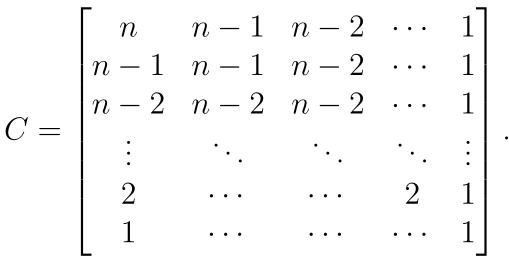

A titolo di esempio, se n = 5 (attenzione: questo numero non soddisfa le condizioni richieste) la matrice C dovrà avere la forma

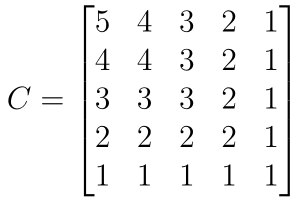

Si calcolino e si visualizzino, inoltre, lo spettro e il raggio spettrale di C. Se il numero inserito non dovesse verificare le condizioni richieste, dovrà esserne richiesto uno nuovo fino a quando non si ottiene un numero consentito.

flag = true;

while flag
    n = input("inserisci un numero intero n pari tra 20 e 30: ");
    if n >= 20 && n <= 30 && (mod(n, 2) == 0)
        flag = false;
    else
        disp("Inserisci un valore valido");
    end
end

C = ones(n);
x = n : -1 : 1;

for i = 1:n
    C(i, :) = x;
    for j = 1:n
        if x(j) == n-i+1
            x(j) = x(j) - 1;
        end
    end
end

C

C =     22    21    20    19    18    17    16    15    14    13    12    11    10     9     8     7     6     5     4     3     2     1
    21    21    20    19    18    17    16    15    14    13    12    11    10     9     8     7     6     5     4     3     2     1
    20    20    20    19    18    17    16    15    14    13    12    11    10     9     8     7     6     5     4     3     2     1
    19    19    19    19    18    17    16    15    14    13    12    11    10     9     8     7     6     5     4     3     2     1
    18    18    18    18    18    17    16    15    14    13    12    11    10     9     8     7     6     5     4     3     2     1
    17    17    17    17    17    17    16    15    14    13    12    11    10     9     8     7     6     5     4     3     2     1
    16    16    16    16    16    16    16    15    14    13    12    11    10     9     8     7     6     5     4     3     2     1
    15    15    15    15    15    15    15    15    14    13    1


[V, D] = eig(C);          %autovalori della matrice
%V = Autovettori
%D = Autovalori
SpettroC = diag(D)

SpettroC =     0.2512
    0.2549
    0.2613
    0.2706
    0.2831
    0.2996
    0.3207
    0.3476
    0.3820
    0.4260
    0.4831
    0.5584
    0.6596
    0.7995
    1.0000



RaggioSpettraleC = max(abs(SpettroC))

RaggioSpettraleC = 205.2588

clc;
clear;
close all;

## Esercizio 2

crei un test per la risoluzione di un sistema lineare Ax = b tramite la fattorizzazione P A = LU della matrice dei coefficienti. In particolare, si generino 10 matrici di dimensione crescente tra 100 e 1000 con passo 100 contenente numeri pseudo-casuali reali compresi tra 10 e 30. Per ogni matrice:

• calcolare la fattorizzazione tramite una funzione [P,L,U] = gauss_palu(A) da allegare alla fine dello script;

• imporre una soluzione x di elementi uguali a 1 e calcolare il corrispondente termine noto b;

• risolvere i sistemi “a cascata” per ottenere la soluzione x1 ;

• calcolare l’errore relativo tra la soluzione vera x e quella calcolata x1 .

Infine, stampare a video una tabella che contiene in ogni riga la dimensione della matrice e l’errore relativo calcolato precedentemente.

iMin = 10;
iMax = 30;
j = 1;
errRel = zeros(10, 1);

for i = 100 : 100 : 1000
    A = (iMax-iMin) * rand(i) + iMin;

    [P, L, U] = gauss_palu(A);

    x = ones(i, 1);
    b = A*x;

    y = L\(P*b);
    x1 = U\y;

    errRel(j) = norm(x - x1) / norm(x);
    j = j + 1;
end

vett = (100 : 100 : 1000)';

t = table(vett, errRel, 'VariableNames', {'Dimensione', 'ErrRel'});
disp(t)

    Dimensione      ErrRel  
    __________    __________

        100       2.3527e-13
        200       1.5197e-12
        300       5.6526e-13
        400       1.3296e-12
        500       2.3736e-12
        600       3.4202e-12
        700       2.1388e-11
        800       1.3705e-11
        900       9.7894e-10
       1000       3.7116e-12



clc;
clear;
close all;

## Esercizio 3

implementi un test per l’approssimazione della radice positiva dell’equazione nonlineare

utilizzando il metodo di Newton, con punto iniziale x0 = 1, e con il metodo di bisezione, partendo dall’intervallo [0, 4]. Per entrambi i metodi, impostare una tolleranza τ = 10e−5 e un numero massimo di iterazioni kmax = 100. Infine si stampi, sullo stesso sistema di assi cartesiani, il grafico della funzione f (x) e le due approssimazioni ottenute. Il grafico dovrà essere corredato da un titolo e una legenda. Le due funzioni 

• [xn ,kn] = newton(f,fder,x0 ,τ ,kmax)

• [xb ,kb] = bisezione(f,a,b,τ ,kmax)

dovranno essere allegate alla fine dello script.

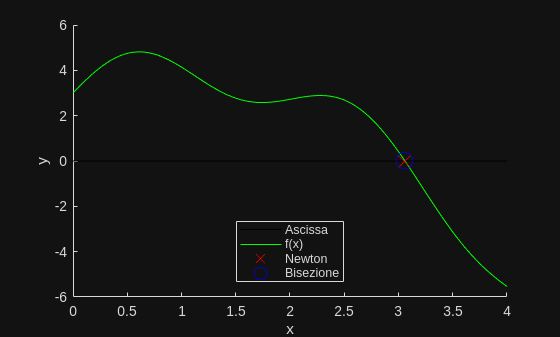

f = @(x) sin(3 .* x) - x.^2 + 2.*x + 3;
fder = @(x) 3.*cos(3.*x) - 2.*x + 2;

tau = 10e-5;
x0 = 1;
a = 0;
b = 4;
kmax = 100;

[xn, kn] = newton(f, fder, x0, tau, kmax);
[xb, kb] = bisezione(f, a, b, tau, kmax);

x = linspace(0, 4, 200);

figure;
hold on;

plot(x, zeros(size(x)), "-k", "DisplayName", "Ascissa");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(xn, f(xn), "xr", "DisplayName", "Newton", "MarkerSize", 12);
plot(xb, f(xb), "ob", "DisplayName", "Bisezione", "MarkerSize", 12);

xlabel("x");
ylabel("y");

legend("Location", "best");

hold off;

function [P, L, U] = gauss_palu(A)

    [m, n] = size(A);
    if m ~= n
        error("La matrice deve essere quadrata");
    end

    if abs(det(A)) < 1e-10
        error("La matrice A è singolare");
    end

    L = zeros(n);
    P = eye(n);

    for k = 1 : n-1

        [~, index] = max(abs(A(k:n, k)));
        l = index + k - 1;

        A([k l], :) = A([l k], :);
        L([k l], :) = L([l k], :);
        P([k l], :) = P([l k], :);
        
        for i = k+1 : n
            m = A(i, k) / A(k, k);

            A(i, :) = A(i, :) - m * A(k, :);

            L(i, k) = m;
        end
    end
    U = A;
    L = L + eye(n);
end

function [xb, kb] = bisezione(f, a, b, tau, kmax)
    
    % bisezione: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0 
    %   [xb, kb] = bisezione(f, a, b, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.


    % Inizializzo la variabile fa con f(a) per non doverla calcolare più
    % volte
    fa = f(a);

    % Controllo che nell'intervallo sia contenuta la radice che cerco
    if(fa * f(b) > 0)
        error("Nessuna radice nell'intervallo [%g, %g]", a, b);
    end


    % Inizio algoritmo iterativo da k a kmax
    for kb = 1 : kmax
       
        % Formula bisezione
        xb = (a + b) / 2;
        
        % Aggiorno l'immagine della x trovata per non doverla calcolare più
        % volte
        fxb = f(xb);

        % Controllo la positività dell'immagine trovata e aggiorno
        % l'intervallo
        if(fa * fxb < 0)
            b = xb;
        else
            a = xb;
            fa = fxb;
        end
        
        % Condizioni di arresto
        if abs(fxb) < tau
            return;
        end

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end

function [xn, kn] = newton(f, fder, x0, tau, kmax)

    % newton: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0
    %   [xn, kn] = newton(f, fder, x0, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.


    % Inizializzo xn
    xn = x0;

    % Se il punto passato è già soluzione lo restituisco
    if(abs(f(x0)) < tau)
        kn = 0;
        return;
    end

    % Inizio algoritmo iterativo da k a kmax
    for kn = 1 : kmax
        
        f1 = fder(x0);

        if(abs(f1) < tau)
            error("La derivata tende a 0: cambia il valore x0");
        end

        % Formula Newton
        xn = x0 - f(x0) / f1;

        % Condizioni di arresto: se la soluzione non è variata
        % significativamente dall'iterazione precedente o se l'immagine
        % risulta abbastanza vicina a 0
        if abs(f(xn)) < tau || abs(xn - x0) < tau * abs(x0)
            return;
        end

        % Aggiornamento variabili
        x0 = xn;

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end